clc; clear; close all
cd 'G:\Jiaxu Flashdrive Backup\GPR model'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'

gau_top_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\gau gpr test\test20\from top");
gau_bot_imds = imageDatastore("G:\Jiaxu Flashdrive Backup\GPR model\gpr test images\gau gpr test\test20\from bot");
load('gpr_models.mat');

%%%%%%%%%%%%%%%%%%%%% top %%%%%%%%%%%%%%%%%%%%%
for i = 1:length(gau_top_imds.Files)
    gau_img_top(:,:,i) = readimage(gau_top_imds,i);
end

for i = 1:length(gau_top_imds.Files)
    norm_img_top(:,:,i) = normlize_image(gau_img_top(:,:,i),255);
    w = 8;
    gau_sharp_top(i) = Gaussian_derivative(norm_img_top(:,:,i),w);
end
norm_gau_sharp_top = norm_array(gau_sharp_top,'gaussian');
norm_gau_sharp_top_combine = [norm_gau_sharp_top, flip(norm_gau_sharp_top(1:5))];

gau_top_height = linspace(0,5,6);
gau_top_height_combine = [gau_top_height,flip(gau_top_height(1:5))];

for i = 1:length(norm_gau_sharp_top_combine)
    bre_top_h_pred(i) = predict(gpr_gau_top,norm_gau_sharp_top_combine(i));
end
%%%%%%%%%%%%%%%%%%%%% bot %%%%%%%%%%%%%%%%%%%%%
for i = 1:length(gau_bot_imds.Files)
    gau_img_bot(:,:,i) = readimage(gau_bot_imds,i);
end

for i = 1:length(gau_bot_imds.Files)
    norm_img_bot(:,:,i) = normlize_image(gau_img_bot(:,:,i),255);
    w = 8;
    gau_sharp_bot(i) = Gaussian_derivative(norm_img_bot(:,:,i),w);
end
norm_gau_sharp_bot = norm_array([gau_sharp_top(1) gau_sharp_bot],'gaussian');
norm_gau_sharp_bot_combine = [norm_gau_sharp_bot(2:end), flip(norm_gau_sharp_bot(1:5))];

gau_bot_height = linspace(-1,-5,5);
gau_bot_height_combine = [gau_bot_height,flip(gau_bot_height(1:4)),0];

for i = 1:length(norm_gau_sharp_bot_combine)
    gau_bot_h_pred(i) = predict(gpr_gau_bot,norm_gau_sharp_bot_combine(i));
end

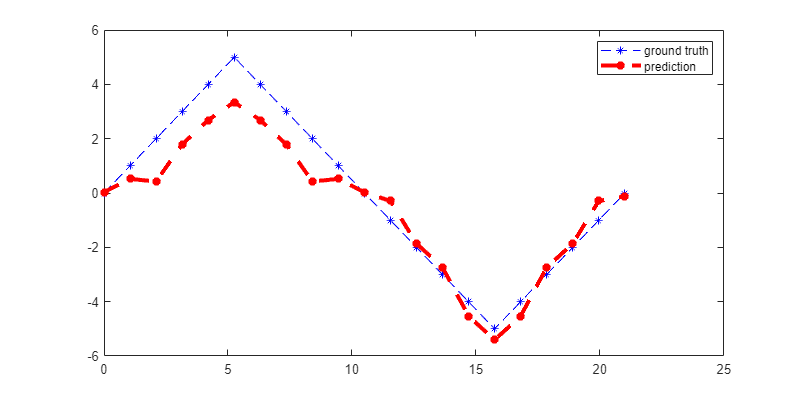

figure(1)
height_out = [gau_top_height_combine';gau_bot_height_combine'];
norm_sharp = [norm_gau_sharp_top_combine';norm_gau_sharp_bot_combine'];
prediction = [bre_top_h_pred';gau_bot_h_pred'];

x_axis = length(norm_gau_sharp_top_combine)+length(norm_gau_sharp_bot_combine);
plot(linspace(0,x_axis,x_axis),[gau_top_height_combine,gau_bot_height_combine],'b--*'); hold on;
plot(linspace(0,x_axis,x_axis),[bre_top_h_pred,gau_bot_h_pred],'r--*',LineWidth=3); hold on
legend('ground truth','prediction')
hold off
x0=0; y0=0;
width=800;
height=400;
set(gcf,'position',[x0,y0,width,height])

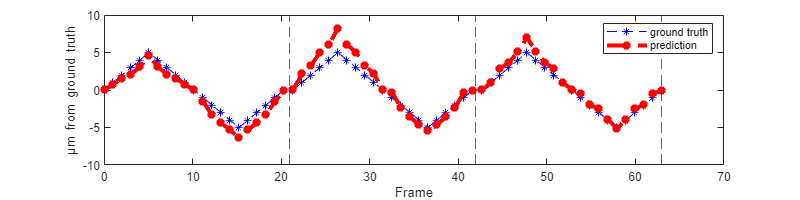

gau_test_result = importdata('gaussian_gpr_test_result_from_3_experiment.txt');

x_axis = length(gau_test_result);
plot(linspace(0,x_axis,x_axis),gau_test_result(:,1),'b--*'); hold on;
plot(linspace(0,x_axis,x_axis),gau_test_result(:,3),'r--*',LineWidth=3); hold on

xline(21,'--'); hold on
xline(21*2,'--'); hold on
xline(21*3,'--');
hold off
legend('ground truth','prediction')
xlabel('Frame');
ylabel('\mum from ground truth')
x0=0; y0=0;
width=800;
height=200;
set(gcf,'position',[x0,y0,width,height])